clear
clc
close all
addpath('helper_functions')
run("/home/rishabh/vlfeat-0.9.21/toolbox/vl_setup.m");

## Setup

path to the images folder

% path_img_dir = '../data/tracking/valid/img';
path_img_dir = '../data/tracking/validation/img';
% path to object ply file
object_path = '../data/teabox.ply';
% path to results folder
results_path = '../data/tracking/valid/results';

% Read the object's geometry 
% Here vertices correspond to object's corners and faces are triangles
[vertices, faces] = read_ply(object_path);

% Create directory for results
if ~exist(results_path,'dir') 
    mkdir(results_path); 
end

% Load Ground Truth camera poses for the validation sequence
% Camera orientations and locations in the world coordinate system
load('gt_valid.mat')

% TODO: setup camera parameters (camera_params) using cameraParameters()
% A - The camera instrinsic matrix
fx = 2960.37845;
fy = 2960.37845;
cx = 1841.68855;
cy = 1235.23369;
A = [fx, 0, 0; 0, fy, 0; cx, cy, 1];

image_size = [2456, 3680];
camera_params = cameraParameters("IntrinsicMatrix",A, "ImageSize",image_size);

## Get all filenames in images folder

FolderInfo = dir(fullfile(path_img_dir, '*.JPG'));
Filenames = fullfile(path_img_dir, {FolderInfo.name} );
num_files = length(Filenames);

% Place predicted camera orientations and locations in the world coordinate system for all images here
cam_in_world_orientations = zeros(3,3,num_files);
cam_in_world_locations = zeros(1,3,num_files);

## Detect SIFT keypoints in all images

% You will need vl_sift() and vl_ubcmatch() functions
% download vlfeat (http://www.vlfeat.org/download.html) and unzip it somewhere
% Don't forget to add vlfeat folder to MATLAB path

% Place SIFT keypoints and corresponding descriptors for all images here
% keypoints = cell(num_files,1); 
% descriptors = cell(num_files,1); 
% 
% for i=1:length(Filenames)
%     fprintf('Calculating sift features for image: %d \n', i)
%     
% %    TODO: Prepare the image (img) for vl_sift() function
% %  Covert images to grayscale as required by vl_sift()
%     gray_img = rgb2gray(imread(Filenames{i}));
% %   Convert to single precision matrix
%     img = single(gray_img);
%     [keypoints{i}, descriptors{i}] = vl_sift(img) ;
% end
% 
% % Save sift features and descriptors and load them when you rerun the code to save time
% save('sift_descriptors.mat', 'descriptors')
% save('sift_keypoints.mat', 'keypoints')

load('sift_descriptors.mat');
load('sift_keypoints.mat');
% Load the sift model as well
load('sift_model.mat')

## Initialization: Compute camera pose for the first image

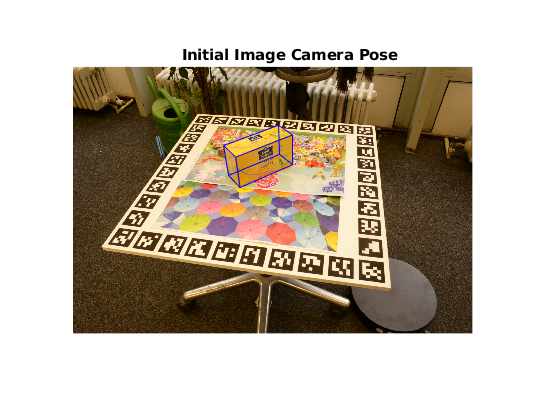

% As the initialization step for the tracking
% we need to compute the camera pose for the first image 
% The first image and it's camera pose will be our initial frame and initial camera pose for the tracking process

% Placing matches between new SIFT features and SIFT features from the SIFT
% model here
sift_matches=cell(num_files,1);
initial_image = 1;

% Default threshold for SIFT keypoints matching: 1.5 
% When taking higher value, match is only recognized if similarity is very high
threshold_ubcmatch = 2.1;

% Match features between SIFT model and SIFT features from new image
% [MATCHES,SCORES] = vl_ubcmatch(descriptors{initial_image}, model.descriptors, threshold_ubcmatch);
% sift_matches{initial_image} = [MATCHES;SCORES];
% 
% save('sift_matches.mat', 'sift_matches');

load("sift_matches.mat")

image_points = keypoints{initial_image}(1:2, sift_matches{initial_image}(1, :));
world_points = model.coord3d(sift_matches{initial_image}(2, :), :);

% You can use estimateWorldCameraPose() function or your own implementation
% of the PnP+RANSAC from the previous tasks

% You can get correspondences for PnP+RANSAC either using your SIFT model from the previous tasks
% or by manually annotating corners (e.g. with mark_images() function)


% TODO: Estimate camera position for the first image
[init_orientation, init_location] = estimateWorldCameraPose(image_points', world_points, camera_params, 'MaxReprojectionError', 4, "MaxNumTrials",10000, "Confidence",99.9);

cam_in_world_orientations(:,:, 1) = init_orientation;
cam_in_world_locations(:,:, 1) = init_location;

% Visualise the pose for the initial frame
edges = [[1, 1, 1, 2, 2, 3, 3, 4, 5, 5, 6, 7]
    [2, 4, 5, 3, 6, 4, 7, 8, 6, 8, 7, 8]];
figure()
hold on;
imshow(char(Filenames(1)), 'InitialMagnification', 'fit');
title(sprintf('Initial Image Camera Pose'));
%   Plot bounding box
points = project3d2image(vertices',camera_params, cam_in_world_orientations(:,:,1), cam_in_world_locations(:, :, 1));
for j=1:12
    plot(points(1, edges(:, j)), points(2, edges(:,j)), 'color', 'b');
end
hold off;

## IRLS nonlinear optimisation

% Now you need to implement the method of iteratively reweighted least squares (IRLS)
% to optimise reprojection error between consecutive image frames

% Method steps:
% 1) Project SIFT keypoints from the initial frame (image i) to the object using the
% initial camera pose and the 3D ray intersection code from the task 1. 
% This will give you 3D coordinates (in the world coordinate system) of the
% SIFT keypoints from the initial frame (image i) that correspond to the object
% 2) Find matches between SIFT keypoints from the initial frame (image i) and the
% subsequent frame (image i+1) using vl_ubcmatch() from VLFeat library
% 3) Reproject these matches using corresponding 3D coordinates from the
% step 1 and the initial camera pose back to the subsequent frame (image i+1)
% 4) Compute the reprojection error between pixels from SIFT
% matches for the subsequent frame (image i+1) and from reprojected matches
% from step 3
% 5) Compute Jacobian of the reprojection error with respect to the pose
% parameters and apply IRLS to iteratively update the camera pose for the subsequent frame (image i+1)
% 6) Now the subsequent frame (image i+1) becomes the initial frame for the
% next subsequent frame (image i+2) and the method continues until camera poses for all
% images are estimated

% We suggest you to validate the correctness of the Jacobian implementation
% either using Symbolic toolbox or finite differences approach

% TODO: Implement IRLS method for the reprojection error optimisation

## Plot camera trajectory in 3D world CS + cameras

figure()
% Predicted trajectory
visualise_trajectory(vertices, edges, cam_in_world_orientations, cam_in_world_locations, 'Color', 'b');
hold on;
% Ground Truth trajectory
visualise_trajectory(vertices, edges, gt_valid.orientations, gt_valid.locations, 'Color', 'g');
hold off;
title('\color{green}Ground Truth trajectory \color{blue}Predicted trajectory')

## Visualize bounding boxes

figure()
for i=1:num_files
    
    imshow(char(Filenames(i)), 'InitialMagnification', 'fit');
    title(sprintf('Image: %d', i))
    hold on
    % Ground Truth Bounding Boxes
    points_gt = project3d2image(vertices',camera_params, gt_valid.orientations(:,:,i), gt_valid.locations(:, :, i));
    % Predicted Bounding Boxes
    points_pred = project3d2image(vertices',camera_params, cam_in_world_orientations(:,:,i), cam_in_world_locations(:, :, i));
    for j=1:12
        plot(points_gt(1, edges(:, j)), points_gt(2, edges(:,j)), 'color', 'g');
        plot(points_pred(1, edges(:, j)), points_pred(2, edges(:,j)), 'color', 'b');
    end
    hold off;
    
    filename = fullfile(results_path, strcat('image', num2str(i), '.png'));
    saveas(gcf, filename)
end

## Bonus part

% Save estimated camera poses for the validation sequence using TUM Ground-truth trajectories file
% format: https://vision.in.tum.de/data/datasets/rgbd-dataset/file_formats
% Then estimate Absolute Trajectory Error (ATE) and Relative Pose Error for
% the validation sequence using python tools from: https://vision.in.tum.de/data/datasets/rgbd-dataset/tools

% Save estimated camera poses for the test sequence using TUM Ground-truth
% trajectories file format

% Send us this file with the estimated camera poses for the evaluation
% If the code and results are good you will get a bonus for this exercise
% We are expecting the mean absolute translational error (from ATE) to be
% approximately less than 1cm

% TODO: Estimate ATE and RPE for validation and test sequences